%页码：P38
%作者；暴富
%时间：2024-06-24
%项目：单积分器的一致性分析
%%作9个图，创建三维数组，每个一个切片是一个时间的状态，每一列对应
%%一个拓扑结构的图，一列的一行6个元素对应与6个状态

%并行池的开和关
%parpool%开
%delete(gcp)%关

clc
clear

%%初始化
T = 0.01;
t = 0:T:15;
N = length(t);
X = zeros(6,9,N);%agent初始化,9个系统，一个系统6个状态
I = eye(6);

lineStyles = linspecer(6); % 指定线型颜色,6个状态

%agengt状态初始化
X(1,:,1) = 1;
X(2,:,1) = -1;
X(3,:,1) = 3;
X(4,:,1) = -3;
X(5,:,1) = 5;
X(6,:,1) = -5;

%%L矩阵求解
%%图A的拉普拉斯矩阵
L_a = [ 1  0  -1  0  0  0;...
      -1  2   0  0  0 -1;...
      -1 -1   2  0  0  0;...
       0 -1   0  1  0  0;...
       0  0  -1  0  1  0;...
       0  0   0 -1 -1  2];

%%图B的拉普拉斯矩阵
A_b = [ 0  1   1  0  0  0;...
       1  0   1  1  0  1;...
       1  1   0  0  1  0;...
       0  1   0  0  0  1;...
       0  0   1  0  0  1;...
       0  1   0  1  1  0];
D_b = diag(sum(A_b,2));
L_b = D_b - A_b;


%% 图c的特征值
A_c = [ 0  1   1  1  1  1;...
       1  0   1  1  1  1;...
       1  1   0  1  1  1;...
       1  1   1  0  1  1;...
       1  1   1  1  0  1;...
       1  1   1  1  1  0];
   
D_c = diag(sum(A_c'));
L_c = D_c - A_c;
 
   
   
%% 图d的特征值
A_d = [ 0  0   0  0  0  0;...
       1  0   0  0  0  0;...
       1  0   0  0  0  0;...
       0  1   0  0  0  0;...
       0  0   1  0  0  0;...
       0  0   1  0  0  0];
   
D_d = diag(sum(A_d'));
L_d = D_d - A_d;
   
         
%% 图e的特征值
A_e = [ 0  1   1  1  1  1;...
       1  0   0  0  0  0;...
       1  0   0  0  0  0;...
       1  0   0  0  0  0;...
       1  0   0  0  0  0;...
       1  0   0  0  0  0];
   
D_e = diag(sum(A_e'));
L_e = D_e - A_e;
 
      
   
%% 图f的特征值
A_f = [ 0  0   0  0  0  0;...
       1  0   0  0  0  0;...
       1  0   0  0  0  0;...
       1  0   0  0  0  0;...
       1  0   0  0  0  0;...
       1  0   0  0  0  0];
   
D_f = diag(sum(A_f'));
L_f = D_f - A_f;
      


%% 图g的特征值
A_g = [ 0  1   0  0  0  1;...
       1  0   1  0  0  0;...
       0  1   0  1  0  0;...
       0  0   1  0  1  0;...
       0  0   0  1  0  1;...
       1  0   0  0  1  0];
   
D_g = diag(sum(A_g'));
L_g = D_g - A_g;


%% 图h的特征值
A_h = [ 0  0   0  0  0  1;...
       1  0   0  0  0  0;...
       0  1   0  0  0  0;...
       0  0   1  0  0  0;...
       0  0   0  1  0  0;...
       0  0   0  0  1  0];
   
D_h = diag(sum(A_h'));
L_h = D_h - A_h;


%% 图i的特征值
A_i = [ 0  1   0  0  0  0;...
       1  0   1  0  0  0;...
       0  1   0  1  0  0;...
       0  0   1  0  1  0;...
       0  0   0  1  0  1;...
       0  0   0  0  1  0];
   
D_i = diag(sum(A_i'));
L_i = D_i - A_i;

%%迭代状态
for ii = 2:N

    X(:,1,ii) = (I-T*L_a)*X(:,1,ii-1);
    X(:,2,ii) = (I-T*L_b)*X(:,2,ii-1);
    X(:,3,ii) = (I-T*L_c)*X(:,3,ii-1);
    
    X(:,4,ii) = (I-T*L_d)*X(:,4,ii-1);
    X(:,5,ii) = (I-T*L_e)*X(:,5,ii-1);
    X(:,6,ii) = (I-T*L_f)*X(:,6,ii-1);
    
    X(:,7,ii) = (I-T*L_g)*X(:,7,ii-1);
    X(:,8,ii) = (I-T*L_h)*X(:,8,ii-1);
    X(:,9,ii) = (I-T*L_i)*X(:,9,ii-1);

end

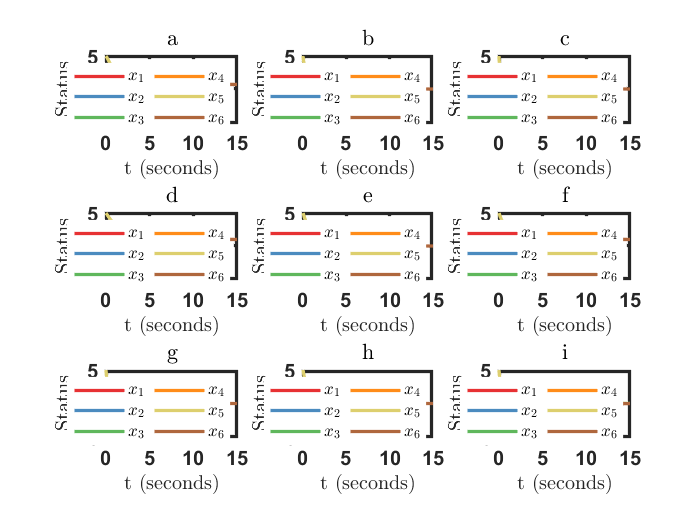

%% 绘制结果
hf = figure;  %新建 图形控制句柄
hf.Color= [1 1 1]; % 控制图形的整体颜色。（scope中被默认为灰黑色，此处修改为白色）

subplot(3,3,1)
%线形设置
plot(t,reshape(X(1,1,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(2,1,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,1,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(4,1,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(5,1,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(6,1,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','a')

subplot(3,3,2)  % 图b
% 线型设置
plot(t,reshape(X(1,2,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(2,2,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,2,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(4,2,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(5,2,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(6,2,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','b')

subplot(3,3,3)  % 图c
% 线型设置
plot(t,reshape(X(1,3,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(2,3,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,3,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(4,3,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(5,3,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(6,3,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','c')


subplot(3,3,4)  % 图d
% 线型设置
plot(t,reshape(X(1,4,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(2,4,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,4,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(4,4,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(5,4,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(6,4,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','d')



subplot(3,3,5)  % 图e
% 线型设置
plot(t,reshape(X(1,5,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(2,5,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,5,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(4,5,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(5,5,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(6,5,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','e')


subplot(3,3,6)  % 图f
% 线型设置
plot(t,reshape(X(1,6,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(2,6,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,6,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(4,6,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(5,6,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(6,6,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','f')


subplot(3,3,7)  % 图g
% 线型设置
plot(t,reshape(X(1,7,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(2,7,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,7,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(4,7,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(5,7,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(6,7,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','g')


subplot(3,3,8)  % 图h
% 线型设置
plot(t,reshape(X(1,8,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(2,8,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,8,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(4,8,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(5,8,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(6,8,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','h')


subplot(3,3,9)  % 图i
% 线型设置
plot(t,reshape(X(1,9,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(2,9,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,9,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(4,9,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(5,9,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(6,9,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','i')